# Tutorial 3 - Yu et al., 2022

## 1.4 Model the Data Generation Process

First let's define the functions

function d_Harm = harm(shocksLarger, shocksSmaller)
    d_Harm = shocksLarger - shocksSmaller;
end
 
function d_Payout = payout(moneyLarger, moneySmaller)
    d_Payout = moneyLarger - moneySmaller;
end

Now let's check and see if they do what we want. Let's make an example trial:

example = table(10, 0, 8, 5, 'VariableNames', ["moneyMore", "moneyLess", "shocksMore", "shocksLess"]);
example

example = 1×4 table
    moneyMore    moneyLess    shocksMore    shocksLess
    _________    _________    __________    __________

       10            0            8             5     


Now get the outputs based on this example

harm(example.shocksMore(1), example.shocksLess(1))

ans = 3

payout(example.moneyMore(1), example.moneyLess(1))

ans = 10

So the choice for more has 3 more harm for 10 more money: that's correct.

## 1.5 Simulating Data

Now let's preallocate and define functions, triallist, and parameters

trialList = table();
trialList.isLeft = repelem([1; 0], 100);
trialList.moneyA = repmat(repelem(11:20, 10), 1, 2)'; 
trialList.moneyB = repmat(10, 1, 200)'; 
trialList.shocksA = repmat(10, 1, 200)';  
trialList.shocksB = repmat(0:9, 1, 20)'; 
trialList

trialList = 200×5 table
    isLeft    moneyA    moneyB    shocksA    shocksB
    ______    ______    ______    _______    _______

      1         11        10        10          0   
      1         11        10        10          1   
      1         11        10        10          2   
      1         11        10        10          3   
      1         11        10        10          4   
      1         11        10        10          5   
      1         11        10        10          6   
      1         11        10        10          7   
      1         11        10        10          8   
      1         11        10        10          9   
      1         12        10        10          0   
      1         12        10        10          1   
      1         12        10        10          2   
      1   

function util = utility(pars, IVs)
    IVs = double(IVs);
    moneyA = IVs(2); moneyB = IVs(3); shocksA = IVs(4); shocksB = IVs(5);
    kappa = pars(1);
    util = kappa * payout(moneyA, moneyB) - (1 - kappa) * harm(shocksA, shocksB);
end

function prob = probability(pars, utilitydiff, IVs)
    isLeft = IVs(1);
    beta = pars(end-2); epsilon = pars(end-1); gamma = pars(end);
    prob = 1 / (1 + exp(-(beta * utilitydiff)));
    if isLeft
        prob = prob * (1 - 2 * epsilon) + epsilon - gamma * (2 * epsilon);
    else
        prob = prob * (1 - 2 * epsilon) + epsilon + gamma * (2 * epsilon);
    end
    prob = max(min(prob, 0.9999999999), 0.00000000001);
end

freeParameters = struct();
kap = (0:0.1:0.9);
bet = [0, 50];
eps = (0:0.1:0.5);
gam = [-0.5, 0];
for i = 1:length(kap)
    for j = 1:length(bet)
        for k = 1:length(eps)
            for l = 1:length(gam)
                freeParameters(i, j, k, l).kappa = kap(i) + rand(1,1)*0.1;
                freeParameters(i, j, k, l).beta = bet(j) + rand(1,1)*50;
                freeParameters(i, j, k, l).epsilon = eps(k);
                freeParameters(i, j, k, l).gamma = gam(l) + rand(1, 1)*0.5;
            end
        end
    end
end

Now that all of that's done, let's generate predictions

freeParameters(i, j, k, l).predictions = zeros(height(trialList), 1);
for i = 1:length(kap)
    for j = 1:length(bet)
        for k = 1:length(eps)
            for l = 1:length(gam)
                pars = [freeParameters(i, j, k, l).kappa, freeParameters(i, j, k, l).beta, freeParameters(i, j, k, l).epsilon, freeParameters(i, j, k, l).gamma];
                for m = 1:height(trialList)
                    IVs = table2array(trialList(m, :));
                    utilityDiff = utility(pars, IVs);
                    prob = probability(pars, utilityDiff, IVs);
                    freeParameters(i, j, k, l).predictions(m) = round(prob.*1000) > randi([1, 1000], 1, 1);
                end  
            end
        end
    end
end 

## 1.6 Compare Recovered Parameters

Let's write the objective function

function obj_val = obj_function_noConditions(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    df.ProbHarm = zeros(height(df), 1);
    for k = 1:height(df)
        IVs = table2array(df(k, 1:5));
        utilityDiff = utility(params, IVs);
        df.ProbHarm(k) = probability(params, utilityDiff, IVs);
    end  
    if strcmp(optimMethod, 'OLS')
        obj_val = sum((df.ChoseHarm - df.ProbHarm) .^ 2);
    else
        obj_val = -sum(df.ChoseHarm .* log(df.ProbHarm) + (1 - df.ChoseHarm) .* log(df.ProbHarm));
    end
end

Now we can set up the optimizer (we'll suppress the output of successful completion to avoid inundating the output)

initial_params = [0.5, 4, 0.25, 0];
lower_bounds = [0, 0, 0, -0.5];
upper_bounds = [1, 100, 0.5, 0.5];

function result = optimize(obj, initial_params, lower_bounds, upper_bounds, df)
    try
        result = fmincon(@(x) obj(x, df, 'OLS'), initial_params, [], [], [], [], lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));
    catch
        result = fmincon(@(x) obj(x, df, 'MLE'), initial_params, [], [], [], [], lower_bounds, upper_bounds, [], optimoptions('fmincon', 'Display', 'off'));
    end
end

And this lets us recover the free parameters 

for i = 1:length(kap)
    for j = 1:length(bet)
        for k = 1:length(eps)
            for l = 1:length(gam)
                trialList.ChoseHarm(:) = freeParameters(i, j, k, l).predictions;
                result = optimize(@obj_function_noConditions, initial_params, lower_bounds, upper_bounds, trialList);
                freeParameters(i, j, k, l).kappaRecovered = result(1);
                freeParameters(i, j, k, l).betaRecovered = result(2);
                freeParameters(i, j, k, l).epsilonRecovered = result(3);
                freeParameters(i, j, k, l).gammaRecovered = result(4);
            end
        end
    end
end 

Let's extract values to format in a plottable way

totalIterations = length(kap) * length(bet) * length(eps) * length(gam);
parsPlot = table();
parsPlot.kappa = NaN(totalIterations, 1);
parsPlot.kappaRecovered = NaN(totalIterations, 1);
parsPlot.beta = NaN(totalIterations, 1);
parsPlot.betaRecovered = NaN(totalIterations, 1);
parsPlot.epsilon = NaN(totalIterations, 1);
parsPlot.epsilonRecovered = NaN(totalIterations, 1);
parsPlot.gamma = NaN(totalIterations, 1);
parsPlot.gammaRecovered = NaN(totalIterations, 1);
m = 0;
for i = 1:length(kap)
    for j = 1:length(bet)
        for k = 1:length(eps)
            for l = 1:length(gam)
                m = m + 1;
                parsPlot.kappa(m) = freeParameters(i, j, k, l).kappa;
                parsPlot.kappaRecovered(m) = freeParameters(i, j, k, l).kappaRecovered;
                parsPlot.beta(m) = freeParameters(i, j, k, l).beta;
                parsPlot.betaRecovered(m) = freeParameters(i, j, k, l).betaRecovered;
                parsPlot.epsilon(m) = freeParameters(i, j, k, l).epsilon;
                parsPlot.epsilonRecovered(m) = freeParameters(i, j, k, l).epsilonRecovered;
                parsPlot.gamma(m) = freeParameters(i, j, k, l).gamma;
                parsPlot.gammaRecovered(m) = freeParameters(i, j, k, l).gammaRecovered;
            end
        end
    end    
end 

So we can now verify that we can reliably recover them using plots

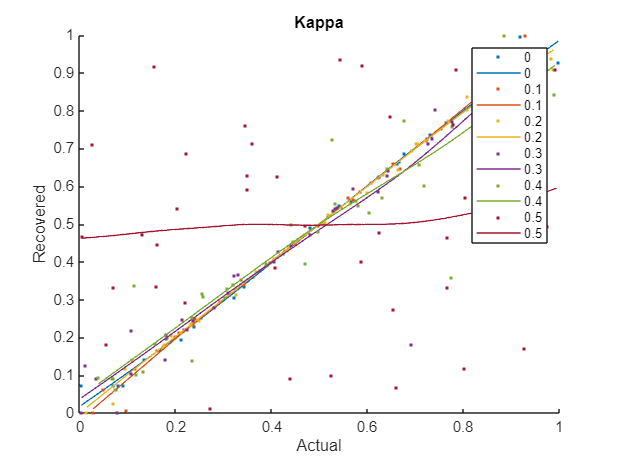

parsPlot.Epsilon = categorical(parsPlot.epsilon);

figure;
hold on
colors = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#A2142F"];
for i = 1:length(eps)
    thisData = parsPlot.epsilon == eps(i);
    Actual = parsPlot.kappa(thisData);
    Recovered = parsPlot.kappaRecovered(thisData);
    f = fit(Actual, Recovered, 'smoothingspline', 'SmoothingParam', 0.99);
    h = plot(f, Actual, Recovered);
    set(h, 'Color', colors(i), 'LineWidth', 1, 'DisplayName', string(eps(i)));
end
hold off;
ylim([0, 1]);
title('Kappa'); xlabel('Actual'); ylabel('Recovered');

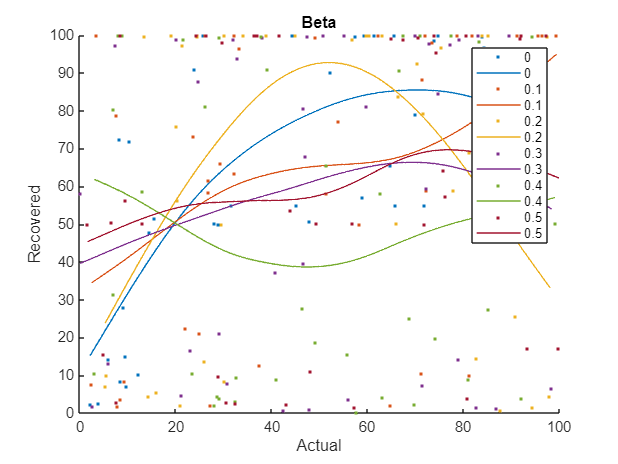

figure;
hold on
colors = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#A2142F"];
for i = 1:length(eps)
    thisData = parsPlot.epsilon == eps(i);
    Actual = parsPlot.beta(thisData);
    Recovered = parsPlot.betaRecovered(thisData);
    f = fit(Actual, Recovered, 'smoothingspline', 'SmoothingParam', 0.0001);
    h = plot(f, Actual, Recovered);
    set(h, 'Color', colors(i), 'LineWidth', 1, 'DisplayName', string(eps(i)));
end
hold off;
ylim([0, 100]);
title('Beta'); xlabel('Actual'); ylabel('Recovered');

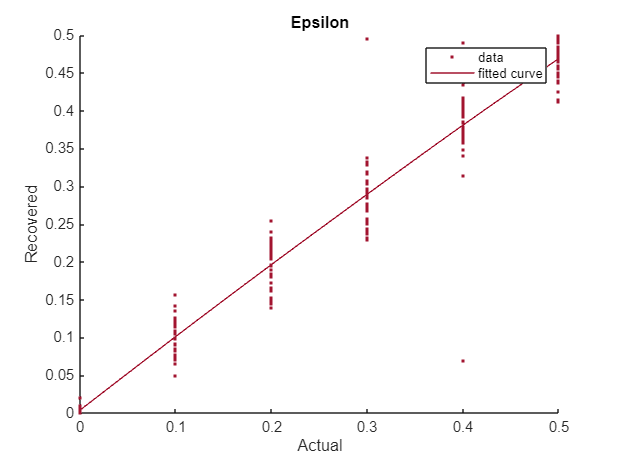

figure;
hold on
f = fit(parsPlot.epsilon, parsPlot.epsilonRecovered, 'smoothingspline', 'SmoothingParam', 0.99);
h = plot(f, parsPlot.epsilon, parsPlot.epsilonRecovered);
set(h, 'Color', colors(i), 'LineWidth', 1);
hold off;
ylim([0, 0.5]);
title('Epsilon'); xlabel('Actual'); ylabel('Recovered');

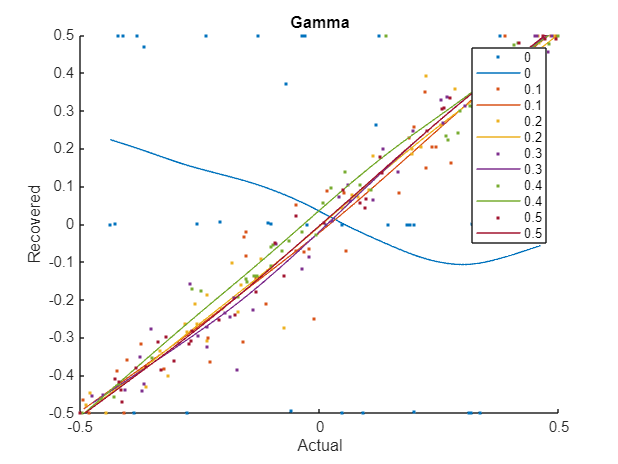

figure;
hold on
colors = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#A2142F"];
for i = 1:length(eps)
    thisData = parsPlot.epsilon == eps(i);
    Actual = parsPlot.gamma(thisData);
    Recovered = parsPlot.gammaRecovered(thisData);
    f = fit(Actual, Recovered, 'smoothingspline', 'SmoothingParam', 0.99);
    h = plot(f, Actual, Recovered);
    set(h, 'Color', colors(i), 'LineWidth', 1, 'DisplayName', string(eps(i)));
end
hold off;
ylim([-0.5, 0.5]);
title('Gamma'); xlabel('Actual'); ylabel('Recovered');

These are a bit more difficult to visually interpret, but nothing looks particularly accurate. Let's take a closer look at situations where we should see good accuracy.

ere does seem to be a positive correlation between these parameters, but it's not particularly reliable. Beta Epsilon, and Gamma are the strongest, Alpha and Delta are pretty poor and Rho seems to be pretty random

## 2.1 Recovering Free Parameters

First let’s get the trial data from participants

trialData = readtable("C:/Users/DELL/Downloads/Data/Data/HPP_fMRI_beh_data_for_lmm.csv")

So we need participants' ID numbers, a0-b2, and their choices in the format 1 or 2. In the above data frame, those are columns 1, 6, 7, 13, 14, 21, 22, and 26 so let's extract those. Also, they only analyzed the rank-reverse condition (perhaps this is why we couldn't reliably recover parameters) so that is "trail_type" 3.

trialData = trialData(trialData.trail_type == 3, [1, 6, 7, 13, 14, 21, 22, 36]);
trialData.Properties.VariableNames = {'SubjectID', 'a0', 'b0', 'a1', 'b1', 'a2', 'b2', 'Chose1'};
trialData.Chose1 = trialData.Chose1 - 1;
trialData.Prob1 = zeros(height(trialData), 1)
function pred = generate_predictions(parameters, df)
pred = zeros(size(df, 1), 1);
for i = 1:size(df, 1)
    thisTrialIVs = table2array(df(i, :));
    utilityDiff = utility(parameters, thisTrialIVs);
    pred(i) = probability(parameters, utilityDiff);
end
end

Now we can define some necessary variables and functions

included_subjects = unique(trialData.SubjectID);

subjectData = table();

grab_data = @(subject) trialData(trialData.SubjectID == subject, 2:end);

function updated = addPredictions(trialData, subject, predictions)
trialData.Prob1(trialData.SubjectID == subject) = predictions;
updated = trialData;
end

Which allows us to Recover Free Parameters and Define Predicted Decisions

for i = 1:length(included_subjects)
    df = grab_data(included_subjects(i));
    result = optimize(@obj_function, initial_params, lower_bounds, upper_bounds, df);

    df.Prob1 = generate_predictions(result, df);
    
    model_SS = sum((df.Chose1 - df.Prob1).^2);
    model_NLL = -2 * sum(df.Chose1 .* log(df.Prob1) + (1 - df.Chose1) .* log(1 - df.Prob1));
    
    subjectData(i, :) = {included_subjects(i), result(1), result(2), result(3), result(4), result(5), result(6), model_SS, model_NLL};
    
    trialData = addPredictions(trialData, included_subjects(i), df.Prob1);
end
subjectData.Properties.VariableNames = {'subjectID', 'Alpha', 'Delta', 'Rho', 'Beta', 'Epsilon', 'Gamma', 'SS', 'Deviance'}

## 2.2 Compute Model Fit Index

We will calculate BIC as the model fit index because we are attempting to model the probabilistic nature of the data generation process.

subjectData.BIC = subjectData.Deviance + log(65) * 6;

## 2.3 Identify the Best Model

We need to define new objective functions for each model. Since each model uses the same utility function, but holds some variables constant (at 0), we only really need to modify the number of parameter inputs and set the constant values to 0. We can also use a list of indices so that the we can use the same function to generate predictions down the line.

function f = of_alphaOnly(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new([1, 4:6]) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_deltaOnly(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new([2, 4:6]) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_rhoOnly(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new(3:6) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_ad(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new([1:2, 4:6]) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_ar(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new([1, 3:6]) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_dr(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new(2:6) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_noEpsilon(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new(1:4) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_noGamma(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new(1:5) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

function f = of_GammaOnly(params, df, optimMethod)
    if nargin < 3
        optimMethod = 'MLE';
    end
    params_new = zeros(1, 6);
    params_new(5) = 0.5;
    params_new(6) = params;
    Prob1 = generate_predictions(params_new, df);
    Chose1 = df.Chose1;
    if strcmp(optimMethod, 'OLS')
        f = sum((Chose1 - Prob1).^2);
    elseif strcmp(optimMethod, 'MLE')
        f = -sum(Chose1 .* log(Prob1) + (1 - Chose1) .* log(1 - Prob1));
    end
end

ofs = {@of_alphaOnly, @of_deltaOnly, @of_rhoOnly, @of_ad, @of_ar, @of_dr, @of_noEpsilon, @of_noGamma, @of_GammaOnly};
idxs = {[1, 4:6], [2, 4:6], 3:6, [1:2, 4:6], [1, 3:6], 2:6, 1:4, 1:5, 6};

And now we can preallocate the predictions for each model and the new data frame

altSubjectData = table();

altTrialData = trialData;
altTrialData.Prob1 = []; % Remove the 9th column
altTrialData.alphaOnly_Prob1 = zeros(height(altTrialData), 1);
altTrialData.deltaOnly_Prob1 = zeros(height(altTrialData), 1);
altTrialData.rhoOnly_Prob1 = zeros(height(altTrialData), 1);
altTrialData.ad_Prob1 = zeros(height(altTrialData), 1);
altTrialData.ar_Prob1 = zeros(height(altTrialData), 1);
altTrialData.dr_Prob1 = zeros(height(altTrialData), 1);
altTrialData.noEpsilon_Prob1 = zeros(height(altTrialData), 1);
altTrialData.noGamma_Prob1 = zeros(height(altTrialData), 1);
altTrialData.gammaOnly_Prob1 = zeros(height(altTrialData), 1);

Now let's Recover Free Parameters and Generate Predictions for this Model

for i = 1:length(included_subjects)
    df = grab_data(included_subjects(i));
    numParams = sum(cellfun(@length, idxs)) + 2 * 9;
    outputs = zeros(1, numParams);
    j = 0;

    for k = 1:length(idxs)
        idx = idxs{k};
        initials = initial_params(idx);
        uppers = upper_bounds(idx);
        lowers = lower_bounds(idx);
        of = ofs{k};

        result = optimize(of, initials, lowers, uppers, df);

        pars = zeros(1, 6);
        pars(idx) = result;
        df.Prob1 = generate_predictions(pars, df);

        model_SS = sum((df.Chose1 - df.Prob1).^2);
        model_NLL = -2 * sum(df.Chose1 .* log(df.Prob1) + (1 - df.Chose1) .* log(1 - df.Prob1));
        outputs((j+1):(j+2+length(result))) = [result, model_SS, model_NLL];
        j = j + 2 + length(result);

        altTrialData{altTrialData.SubjectID == included_subjects(i), (8+k)} = df.Prob1;
    end
    altSubjectData(i, 1:56) = array2table([included_subjects(i), outputs]);
end

altSubjectData.Properties.VariableNames = {'SubjectID', 'Alpha_M1', 'Beta_M1', 'Epsilon_M1', 'Gamma_M1', 'SS_M1', 'Deviance_M1', ...
                                           'Delta_M2', 'Beta_M2', 'Epsilon_M2', 'Gamma_M2', 'SS_M2', 'Deviance_M2', ...
                                           'Rho_M3', 'Beta_M3', 'Epsilon_M3', 'Gamma_M3', 'SS_M3', 'Deviance_M3', ...
                                           'Alpha_M4', 'Delta_M4', 'Beta_M4', 'Epsilon_M4', 'Gamma_M4', 'SS_M4', 'Deviance_M4', ...
                                           'Alpha_M5', 'Rho_M5', 'Beta_M5', 'Epsilon_M5', 'Gamma_M5', 'SS_M5', 'Deviance_M5', ...
                                           'Delta_M6', 'Rho_M6', 'Beta_M6', 'Epsilon_M6', 'Gamma_M6', 'SS_M6', 'Deviance_M6', ...
                                           'Alpha_M7', 'Delta_M7', 'Rho_M7', 'Beta_M7', 'SS_M7', 'Deviance_M7', ...
                                           'Alpha_M8', 'Delta_M8', 'Rho_M8', 'Beta_M8', 'Epsilon_M8', 'SS_M8', 'Deviance_M8', ...
                                           'Gamma_M9', 'SS_M9', 'Deviance_M9'};

altSubjectData(:, 2:end) = varfun(@double, altSubjectData(:, 2:end))

Let's glance at the trial level data for these alternative models.

altTrialData

Now we can compute BIC for these models

n = 65;
altSubjectData.BIC_M1 = altSubjectData.Deviance_M1 + log(n) * 4;
altSubjectData.BIC_M2 = altSubjectData.Deviance_M2 + log(n) * 4;
altSubjectData.BIC_M3 = altSubjectData.Deviance_M3 + log(n) * 4;
altSubjectData.BIC_M4 = altSubjectData.Deviance_M4 + log(n) * 5;
altSubjectData.BIC_M5 = altSubjectData.Deviance_M5 + log(n) * 5;
altSubjectData.BIC_M6 = altSubjectData.Deviance_M6 + log(n) * 5;
altSubjectData.BIC_M7 = altSubjectData.Deviance_M7 + log(n) * 4;
altSubjectData.BIC_M8 = altSubjectData.Deviance_M8 + log(n) * 5;
altSubjectData.BIC_M9 = altSubjectData.Deviance_M9 + log(n) * 1;

And now we can compare the BIC of all models

modelBIC = [sum(subjectData.BIC), sum(altSubjectData.BIC_M1), sum(altSubjectData.BIC_M2), sum(altSubjectData.BIC_M3), sum(altSubjectData.BIC_M4), ...
            sum(altSubjectData.BIC_M5), sum(altSubjectData.BIC_M6), sum(altSubjectData.BIC_M7), sum(altSubjectData.BIC_M8), sum(altSubjectData.BIC_M9)];

[minBIC, idx] = min(modelBIC);
disp(idx);

So model 4, which has everything except Rho

## 2.4 Validate the Best Model

First, let’s assess model performance at a basic level: we can look at prediction accuracy to begin

sum(altTrialData.Chose1 == round(altTrialData.ad_Prob1))/height(altTrialData)

Next, we can proceed to look at the distribution of model accuracy across participants:

[f, xi] = ksdensity(altSubjectData.BIC_M4);
plot(xi, f);
title('Density of BIC M4');
xlabel('BIC M4');
ylabel('Density');

Let’s look at the bottom 25% of model performance:

Q3 = prctile(altSubjectData.BIC_M4, 75);
worstExplained = find(altSubjectData.BIC_M4 > Q3);

filteredData = altTrialData(ismember(altTrialData.SubjectID, altSubjectData.SubjectID(worstExplained)), :);

x_diff = filteredData.a0 - filteredData.a1;
y_diff = filteredData.Chose1 - filteredData.ad_Prob1;

figure;
hold on;
uniqueSubjects = unique(filteredData.SubjectID);
colors = lines(length(uniqueSubjects));
for i = 1:length(uniqueSubjects)
    idx = filteredData.SubjectID == uniqueSubjects(i);
    scatter(x_diff(idx), y_diff(idx), [], 'Color', colors(i));
    lsline;
end
hold off;
xlabel('a0 - a1');
ylabel('Chose1 - ad\_Prob1');

Nothing systematic here

x_diff = filteredData.a0 - filteredData.a2;

figure;
hold on;
uniqueSubjects = unique(filteredData.SubjectID);
colors = lines(length(uniqueSubjects));
for i = 1:length(uniqueSubjects)
    idx = filteredData.SubjectID == uniqueSubjects(i);
    scatter(x_diff(idx), y_diff(idx), [], 'Color', colors(i));
    lsline;
end
hold off;
xlabel('a0 - a2');
ylabel('Chose1 - ad\_Prob1');

Systematically overpredicting choosing 1 when player A has more and undepredicted when player A has less. This suggests a bias that only seems to apply when looking at choice 2 because we don't see this on choice 1.

x_diff = filteredData.b0 - filteredData.b1;

figure;
hold on;
uniqueSubjects = unique(filteredData.SubjectID);
colors = lines(length(uniqueSubjects));
for i = 1:length(uniqueSubjects)
    idx = filteredData.SubjectID == uniqueSubjects(i);
    scatter(x_diff(idx), y_diff(idx), [], 'Color', colors(i));
    lsline;
end
hold off;
xlabel('b0 - b1');
ylabel('Chose1 - ad\_Prob1');

This is fine

x_diff = filteredData.b0 - filteredData.b2;

figure;
hold on;
uniqueSubjects = unique(filteredData.SubjectID);
colors = lines(length(uniqueSubjects));
for i = 1:length(uniqueSubjects)
    idx = filteredData.SubjectID == uniqueSubjects(i);
    scatter(x_diff(idx), y_diff(idx), [], 'Color', colors(i));
    lsline;
end
hold off;
xlabel('b0 - b2');
ylabel('Chose1 - ad\_Prob1');

Same issue as before - so it seems that these people have a preference/bias for player A when player B has more, but this only applies to Choice 1. Not very useful information, but we're dealing with a trialset that is probably too small for the number of participants we have. Anyways, we can't do anything with this information, we can just bear it in mind as we proceed to check assumptions: first linearity (we’ll do this across both choices)

figure;
hold on;

groups = altTrialData.a0 < altTrialData.b0;
uniqueGroups = unique(groups);
titles = ["a0 < b0", "a0 > b0"];
colors = ["r*", "b*"];
for i = 1:length(uniqueGroups)
    idx = groups == uniqueGroups(i);
    plot(altTrialData.ad_Prob1(idx), altTrialData.Chose1(idx), colors(i));
end
lsline;
xlabel('ad\_Prob1');
ylabel('Chose1');
legend(titles)
hold off

This isn't great, but it's fine. Second, normality of error:

residuals = altTrialData.ad_Prob1 - altTrialData.Chose1;
residual_std = std(residuals);
normvals = normrnd(0, residual_std, 1000, 1);
[f, xi] = ksdensity(residuals, 'Bandwidth', residual_std);
[f_norm, xi_norm] = ksdensity(normvals, 'Bandwidth', residual_std);
figure;
hold on;
plot(xi, f, 'LineWidth', 2, 'Color', 'b');
plot(xi_norm, f_norm, 'LineWidth', 2, 'Color', 'r');
xlabel('Residuals');
ylabel('Density');
legend({'Actual', 'Predicted'});
hold off;

Looks very good. Third we can examine homoscedasticity:

x_vals = altTrialData.a1 - altTrialData.a2;
y_vals = altTrialData.ad_Prob1 - altTrialData.Chose1;
scatter(x_vals, y_vals);
hold on;

lsline;

mdl = fitlm(x_vals, y_vals);

[x_sorted, sortIdx] = sort(x_vals);
[y_pred, y_ci] = predict(mdl, x_sorted);

fill([x_sorted; flipud(x_sorted)], [y_ci(:,1); flipud(y_ci(:,2))], 'k', ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none');

xlabel('a1 - a2');
ylabel('ad\_Prob1 - Chose1');
hold off;

Nice constant variance cloud across all X values. And finally independence of error:

figure;
hold on;

groups = altTrialData.a0 < altTrialData.b0;
uniqueGroups = unique(groups);
titles = ["a0 < b0", "a0 > b0"];
colors = ["r*", "b*"];
for i = 1:length(uniqueGroups)
    idx = groups == uniqueGroups(i);
    x = altTrialData.a1(idx) - altTrialData.a2(idx);
    diff = altTrialData.Chose1(idx) - altTrialData.ad_Prob1(idx);
    plot(x, diff, colors(i));
end
lsline;
xlabel('a1 - a2');
ylabel('Chose1 - ad\_Prob1');
legend(titles)
hold off

The model seems to have a slight bias, under-predicting the likelihood of choosing option 1 when Player A has less than Player B and Choice 2 is better for player A. But this seems to not be such a big issue.

Let’s assess the independence: i.e. the extent to which our model captures all differences in choice behavior between different people:

altTrialData.a0greaterThanb0 = altTrialData.a0 > altTrialData.b0
ric_model = fitglme(altTrialData, 'Chose1 ~ ad_Prob1 + a0greaterThanb0 + (1 | SubjectID)', 'Distribution', 'binomial');
ric_model.Rsquared

So there are no convergence warnings here (i.e. that we reached the maximum number of iterations - or attempts to find a solution - without satisfying the tolerance - or the criteria necessary to stop looking). Let's look at the R squared of the standard model for comparison.

model = fitglm(altTrialData, 'Chose1 ~ ad_Prob1', 'Distribution', 'binomial');
model.Rsquared

So there is a lot of unexplained variance in the standard model. Let's compare to the model with only the random intercept now:

ri_model = fitglme(altTrialData, 'Chose1 ~ ad_Prob1 + (1 | SubjectID)', 'Distribution', 'binomial');
ri_model.Rsquared

Wow, so the condition really only explains a very small amount of varance - there's a lot of indivdual variance that the model doesn't pick up. Let's compare this to the 3 norm model:

threeNormmodel = fitglm(trialData, 'Chose1 ~ Prob1', 'Distribution', 'binomial');
threeNormmodel.Rsquared

So somehow there's a lot of indivdual variance that our models just don't detect whatsoever. Let's see if we can trigger a convergence warning by including a random intercept of condition.

ris_model = fitglme(altTrialData, 'Chose1 ~ ad_Prob1 + a0greaterThanb0 + (1 + a0greaterThanb0 | SubjectID)', 'Distribution', 'binomial');
ris_model.Rsquared

No convergence warnings even here. Okay, let's take it onboard that our model is somehow missing 20% of the apparent variance in this behavior. We can proceed to fivefold validation

fivefold = table();
trialData.Prob1_ff = zeros(height(trialData), 1);
for i = 1:length(included_subjects)
    df = grab_data(included_subjects(i));
    df.Prob1 = zeros(height(df), 1);
    order = randperm(height(df));
    A_ff = zeros(1, 5);
    D_ff = zeros(1, 5);  
    B_ff = zeros(1, 5);
    E_ff = zeros(1, 5);
    G_ff = zeros(1, 5);
    df.Pred = zeros(height(df), 1);

    for z = 1:5
        j = round((z - 1) * (height(df) / 5) + 1);
        n = round(z * (height(df) / 5));
        withheld = order(j:n);

        result_ff = optimize(@of_ad, initial_params([1, 2, 4:6]), lower_bounds([1, 2, 4:6]), upper_bounds([1, 2, 4:6]), df(~ismember(1:height(df), withheld), :));
        
        A_ff(z) = result_ff(1);
        D_ff(z) = result_ff(2);  
        B_ff(z) = result_ff(3);
        E_ff(z) = result_ff(4);
        G_ff(z) = result_ff(5);

        pars = [result_ff(1:2), 0, result_ff(3:5)];
        df.Prob1(withheld) = generate_predictions(pars, df(withheld, :));
    end

    Deviance_ff = -2 * sum(df.Chose1 .* log(df.Prob1) + (1 - df.Chose1) .* log(1 - df.Prob1));
    fivefold(i, 1:27) = {included_subjects(i), Deviance_ff, ...
        A_ff(1), A_ff(2), A_ff(3), A_ff(4), A_ff(5), ... 
        D_ff(1), D_ff(2), D_ff(3), D_ff(4), D_ff(5), ...
        B_ff(1), B_ff(2), B_ff(3), B_ff(4), B_ff(5), ...
        E_ff(1), E_ff(2), E_ff(3), E_ff(4), E_ff(5), ...
        G_ff(1), G_ff(2), G_ff(3), G_ff(4), G_ff(5)};
    trialData.Prob1_ff(trialData.SubjectID == included_subjects(i)) = df.Prob1;
end

fivefold.Properties.VariableNames = {'SubjectID', 'Deviance', ...
    'A_F1', 'A_F2', 'A_F3', 'A_F4', 'A_F5', ...
    'D_F1', 'D_F2', 'D_F3', 'D_F4', 'D_F5', ...
    'B_F1', 'B_F2', 'B_F3', 'B_F4', 'B_F5', ...
    'E_F1', 'E_F2', 'E_F3', 'E_F4', 'E_F5', ...
    'G_F1', 'G_F2', 'G_F3', 'G_F4', 'G_F5'}

Now we can check the model accuracy

sum(trialData.Chose1 == round(trialData.Prob1_ff))/height(trialData)

That's not such a bad drop in model accuracy - only around 2%. Now let's test it agains the normally recovered model:

fivefold.BIC = fivefold.Deviance + log(65) * 6;
[~, p, ~, stats] = ttest(fivefold.BIC, altSubjectData.BIC_M4); stats.p = round(p, 3)

So it's significantly better, but that's not surprising and not concerning given the small decrease in accuracy. Let's look at the similarlity of the parameters - first, let's compute cosine similarity.

cosines = zeros(1, 25);

function cos = cosine(A, B)
cos = dot(A, B) / (norm(A) * norm(B));
end

for i = 1:5
    cosines(i) = cosine(altSubjectData.Alpha_M4, fivefold{:, i + 2});
    cosines(i + 5) = cosine(altSubjectData.Delta_M4, fivefold{:, i + 7});
    cosines(i + 10) = cosine(altSubjectData.Beta_M4, fivefold{:, i + 12});
    cosines(i + 15) = cosine(altSubjectData.Epsilon_M4, fivefold{:, i + 17});
    cosines(i + 20) = cosine(altSubjectData.Gamma_M4, fivefold{:, i + 22});
end

Now let's see the cosine for all parameters - first alpha:

mean(cosines(1:5))

Very good. Now delta

mean(cosines(6:10))

Again, very good. Now beta

mean(cosines(11:15))

Also good. Now epsilon

mean(cosines(16:20))

Nice. Finally gamma

mean(cosines(21:25))

Everything looks good here. Let's go to the fun part - model testing.

## 3.1 Compare Models

First, let's test the alpha + delta model agains the full model (which has alpha + delta + rho)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, subjectData.BIC); stats.p = round(p, 3)

So M4 has a significantly lower BIC that the full model (i.e. p < 0.001), meaning it is significantly better to ignore rank-reversal. How about the alpha only model (M1)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M1); stats.p = round(p, 3)

So M4 is better, but not significantly better meaning that including harm aversion does not significanlty improve model performance. How about the delta only model (M2)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M2); stats.p = round(p, 3)

So including inequality aversion significantly improves model performance. How about the rho only model (M3)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M3); stats.p = round(p, 3)

Including both inequality aversion and harm aversion significantly improves model performance. Let's look at the inequality and rank reversal aversion model (M5)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M5); stats.p = round(p, 3)

Switching harm aversion for rank reversal aversion does not significanlty lessen model performance. Interesting - now we can examine the harm and rank reversal aversion model (M6)

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M6); stats.p = round(p, 3)

Switching inequality aversion for rank reversal aversion significantly lessens model performance. How about if we remove the noise and bias parameters from the full model

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M7); stats.p = round(p, 3)

So it does significantly hurt the model performance compared to our favored model - but let's compare apples to apples here:

[~, p, ~, stats] = ttest(subjectData.BIC, altSubjectData.BIC_M7); stats.p = round(p, 3)

So including these significantly improves model performance. We may wish to verify by instantiating this model as a variant of M4 instead of the full model, but at the moment it's not extremely urgent to do. Let's move onto M8 which only removes the bias parameter

[~, p, ~, stats] = ttest(subjectData.BIC, altSubjectData.BIC_M8); stats.p = round(p, 3)

It seems that including the bias parameter might not be extremely important, so we again may wish to rerun M8 as a variant of M4. But that is for another time. Let's finish up with M9 and that only has left right preferences

[~, p, ~, stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_M9); stats.p = round(p, 3); stats

So that's significant, but not as big as we might expect.

Here, we can conclude that inequality aversion plays a significant role in these decisions, but harm aversion does not. Also, these decisions tend to be very noisy, but not significantly determined by biases for chosing left versus right. 

## 3.3 Test for Individual Differences

Let’s first recover parameters over the whole dataset and we can assess how accurate it is 

resultNID = optimize(@of_ad, initial_params([1,2,4:6]), lower_bounds([1,2,4:6]), upper_bounds([1,2,4:6]), trialData);
pars = [resultNID(1:2), 0, resultNID(3:5)];
trialData.Prob1_NID = generate_predictions(pars, trialData);
sum(trialData.Chose1 == round(trialData.Prob1_NID))/height(trialData)

Not very good. This isn’t surprising given that people often have very different preferences. Now let’s test for individual differences.

altSubjectData.Deviance_NID = zeros(size(altSubjectData,1), 1);

for i = 1:length(included_subjects)
    trials = find(included_subjects(i) == trialData.SubjectID);
    df = trialData(trials, :);
    altSubjectData.Deviance_NID(i) = -2 * sum(df.Chose1 .* log(df.Prob1_NID) + (1 - df.Chose1) .* log(1 - df.Prob1_NID));
end

altSubjectData.BIC_NID = altSubjectData.Deviance_NID + log(65) * 5 / length(included_subjects);
[~,p,~,stats] = ttest(altSubjectData.BIC_M4, altSubjectData.BIC_NID); stats.p = round(p, 3); stats

Significant individual differences. Let’s see which models are worse

find(modelBIC > sum(altSubjectData.BIC_NID))

So M2 (delta only), M3 (rho only), M6 (delta + rho), M7 (no epsilon or gamma), and M9 (only left/right) are worse than this model